**Задание 6. Решение задач линейного программирования**

**Требуется:**

Решить 7  задач по линейному программированию с помощью процедуры `linprog`**.** 

 
$$\left\lbrack x, fval\right\rbrack =linprog\left(f,A,b,Aeq,beq,lb,ub\right)$$


В задачах 2 – 4 (с двумя неизвестными) дополнительно использовать графический способ решения.

В целочисленных задачах 5 – 7 использовать команду  `intlinprog`, 

 
$$\left\lbrack x, fval\right\rbrack =intlinprog\left(f,intcon,A,b,Aeq,beq,lb,ub\right)$$
 

указывая  вектор с индексами целочисленных переменных  


$$\mathrm{intcon}=\left\lbrack 1\text{ }2\text{ }3\text{ }4\text{ }5\text{ }6\right\rbrack$$


При составлении отчетов  в  Word  для текстовых задач  2 - 7 требуется предварительно представить  их в виде уравнений и неравенств, используя редактор формул, т.е.  в таком же виде, какой имеет первая задача.

**ЗАДАЧА 1.**


$$\begin{cases}

f(x) = 3*x_{1} + x_{2} + 2*x_{3} 
\\
x_{1} + x_{2} + x_{3} >1
\\
2*x_{1} + x_{2} - x_{3} > -1
\\
x_{1} - x_{2} + x_{3} = 0
\\
0 \leq x_{1} \leq 1
\\
0 \leq x_{2} \leq 1
\\
0 \leq x_{3} \leq 1
\\
\end{cases}$$


C= [3 1 2];
D = [1 1 1; 2 1 -1];
B = [1 -1];
Aeq = [1 -1 1];
beq = [0];
lb = zeros(3,1);
ub = [1 1 1];
f = C;
A = -D;
b = -B;
[x,fval] = linprog(f,A,b,Aeq,beq,lb,ub)


Optimal solution found.



x =          0
    0.5000
    0.5000


fval = 1.5000

**ЗАДАЧА**** 2.** Фирма изготавливает два вида красок для внутренних (В) и наружных (Н) работ. Для этих производств используют исходные продукты: пигмент и олифу. Расходы исходных продуктов и их максимальные суточные запасы указаны в таблице.

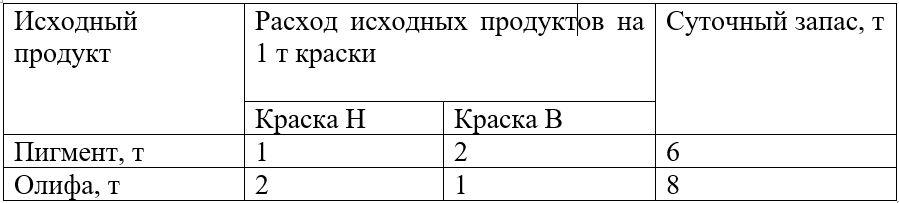

Изучение рынка сбыта показало, что суточный спрос на краску для наружных (внутренних) работ никогда не превышает 2 в сутки. Цена продажи 1т краски для наружных работ составляет 3000 ден. ед., для внутренних – 2000 ден.ед.  Какое количество краски каждого вида должна производить фирма, чтобы доход от реализации был максимальным?


$$\begin{cases}
f(x) = x_1*3000 + x_2*2000 \rightarrow max
\\
x_1 + x_2*2 \leq 6
\\
x_1*2 + x_2 \leq 8
\\
0 \leq x_1 \leq 2
\end{cases}$$


% --Аналитическое решение--
f = [3000 2000];
A = [1 2;
    2 1];
b = [6; 8];
Aeq = [0 0];
beq = 0;
lb = [0; 0];
ub = [2; 150];
[x, fval] = linprog(-f, A, b, Aeq, beq, lb, ub)


Optimal solution found.



x =      2
     2


fval = -10000


% --Графическое решение--
x1 = 0:0.1:20;
x21 = (6 - x1)./2;
x22 = 8 - 2.*x1;
figure('Name', 'Графическое решение', 'NumberTitle', 'off');
title('Графическое решение');
grid on;
hold on;
% --Построение диний ограничений--
plot(x1, x21, 'Color', 'blue');
plot(x1, x22, 'Color', 'magenta');
xlim([0 8]);
ylim([0 8]);
xlabel('X1');
ylabel('X2');

Коэффициенты в векторе градиента будут равны коэффициентам при $x_1
$ и $x_2
$ соответственно, так как: $\frac{\mathrm{df}}{dx_1 }=3000,\frac{\mathrm{df}}{dx_2 }=2000$.

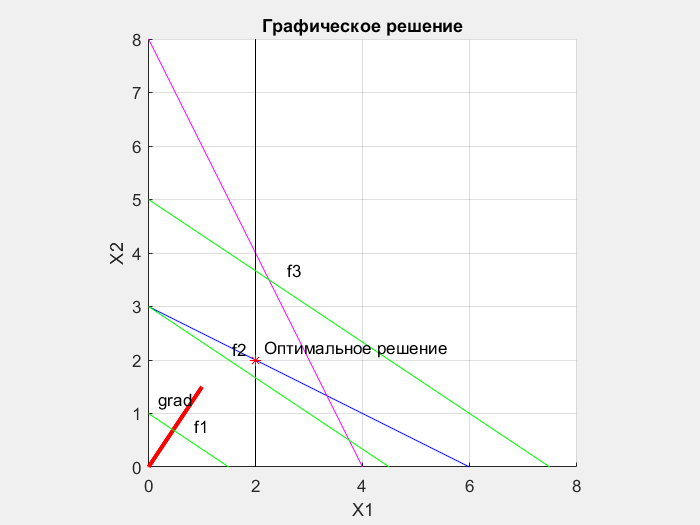

% --Построение вектора градиента--
fun = @(x) 3000/2000 .* x;
fplot(fun, [0 1], 'LineWidth', 2.5, 'Color', 'red');
gtext('grad');

% --Линия ограничения X1--
line([2; 2], [0; 14], 'Color', 'black');

f = {'f1','f2','f3'}; 
Val = [1 3 5];
for i = 1:3;
    C1 = Val(i); 
fplot(@(X1) C1 - 2000/3000*X1, 'g');
gtext(f{i});
end;
axis equal;
axis([0 8 0 8]);
plot(2, 2, '*', 'Color', 'red');
gtext('Оптимальное решение');

**ЗАДАЧА ****3.** Кондитерская фабрика при производстве двух видов карамели – «Снежинка» и «Яблочная» - использует три вида основного сырья: сахарный песок, патоку и фруктовое пюре. Запасы сырья составляют соответственно  800 т, 600 т и 120 т. Выручка от реализации 1 т «Снежинки» составляет 108 ед.ден., а «Яблочной» - 140 ед.ден. На выпуск 1 т «Снежинки» расходуется 0.8 т сахара, 0.2 т патоки и 10 кг фруктового пюре, а на выпуск 1 т «Яблочной» - соответственно по 0.5 т, 0.4 т и 0.1 т этих видов сырья.

Необходимо найти план производства карамели, позволяющий получить наибольшую выручку.

 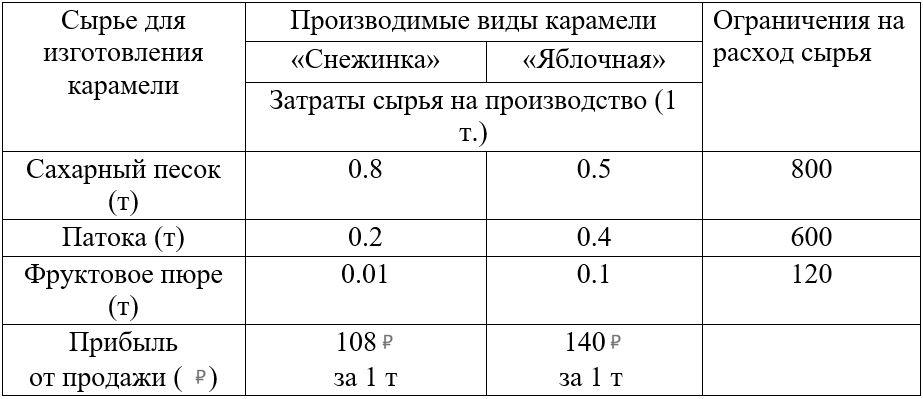


$$\begin{cases}
x_1*108+x_2*140 \rightarrow max
\\
0.8*x_1 + 0.5*x_2 \leq 800
\\
0.2*x_1 + 0.4*x_2 \leq 600
\\
0.01*x_1 + 0.1*x_2 \leq 120
\\
0 \leq x_1
\\
0 \leq x_2
\end{cases}$$


% --Аналитический способ--
f = [108 140];
A = [0.8 0.5;
    0.2 0.4;
    0.01 0.1];
b = [800; 600; 120];
Aeq = [0 0];
beq = 0;
lb = [0; 0];
[x, fval] = linprog(-f, A, b, Aeq, beq, lb)


Optimal solution found.



x =    1.0e+03 *

    0.2667
    1.1733


fval = -1.9307e+05

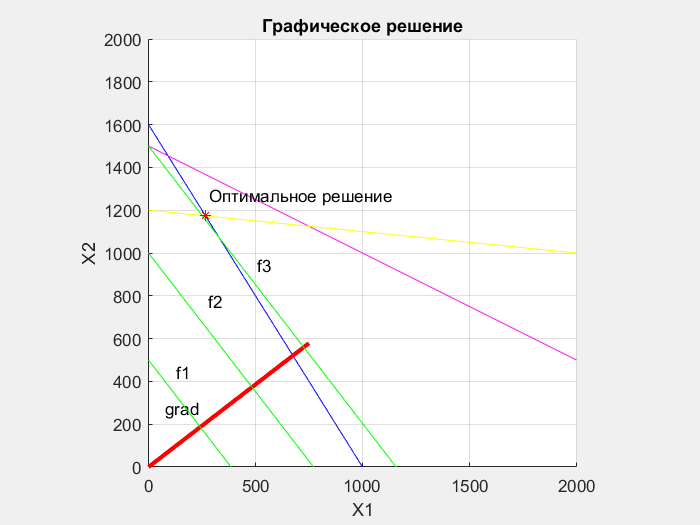


% --Графический способ--
x1 = 0:0.1:5000;
x21 = (800 - 0.8*x1)./0.5;
x22 = (600 - 0.2.*x1)./0.4;
x23 = (120 - 0.01.*x1)./0.1;
figure('Name', 'Графическое решение', 'NumberTitle', 'off');
title('Графическое решение');
grid on;
hold on;
% --Построение диний ограничений--
plot(x1, x21, 'Color', 'blue');
plot(x1, x22, 'Color', 'magenta');
plot(x1, x23, 'Color', 'yellow');
xlim([0 2000]);
ylim([0 2000]);
xlabel('X1');
ylabel('X2');

% --Построение вектора градиента--
fun = @(x) 108/140 .* x;
fplot(fun, [0 750], 'LineWidth', 2.5, 'Color', 'red');
gtext('grad');

f = {'f1','f2','f3'}; 
Val = [500 1000 1500];
for i = 1:3;
    C1 = Val(i); 
fplot(@(X1) C1 - 140/108*X1, 'g');
gtext(f{i});
end;
axis equal;
axis([0 2000 0 2000]);
plot(266.6667, 1173.33, '*', 'Color', 'red');
gtext('Оптимальное решение');

**ЗАДАЧА ****4.** Организации, занимающейся перевозкой и продажей продукции, необходимо перевезти партию товара. При этом можно арендовать для перевозки по железной дороге 5- и 7-тонные контейнеры. Пятитонных контейнеров имеется в наличии не более 18 штук, и семитонных – не более 18 штук. На перевозку всей продукции по смете выделено не более 60 тыс руб, причем цена за аренду пятитонного контейнера составляет 2 тыс. руб, семитонного – 3 тыс. руб. Определить, сколько и каких контейнеров следует арендовать, чтобы общий объем грузоперевозок был максимальным.

 
$$\begin{cases}
5*x_1 + 7*x_2 \rightarrow max
\\
2*x_1 + 3*x_2 \leq 60
\\
0 \leq x_1 \leq 18
\\
0 \leq x_2 \leq 18
\end{cases}$$


% --Аналитический способ--
f = [5 7];
A = [2 3];
b = [60];
Aeq = [0 0];
beq = 0;
lb = [0; 0];
ub = [18; 18];
[x, fval] = linprog(-f, A, b, Aeq, beq, lb, ub)


Optimal solution found.



x =     18
     8


fval = -146

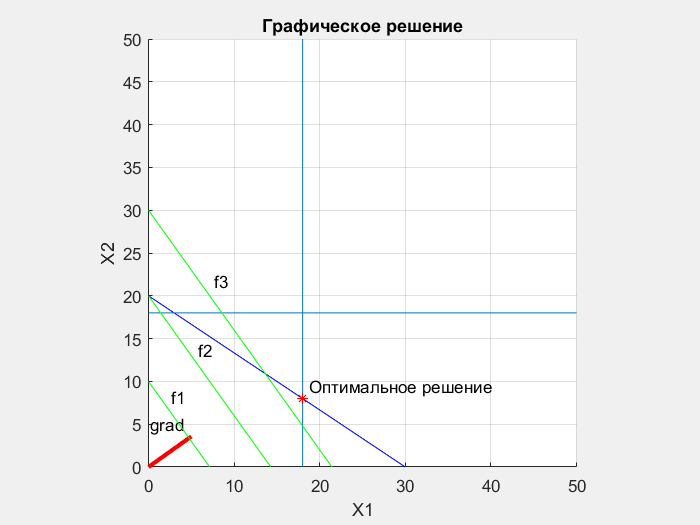


% --Графический способ--
x1 = 0:0.1:50;
x21 = (60 - 2*x1)./3;
figure('Name', 'Графическое решение', 'NumberTitle', 'off');
title('Графическое решение');
grid on;
hold on;
% --Построение диний ограничений--
plot(x1, x21, 'Color', 'blue');
line([18 18], [0 100]);
line([0 100], [18 18]);
xlim([0 50]);
ylim([0 50]);
xlabel('X1');
ylabel('X2');

% --Построение вектора градиента--
fun = @(x) 5/7 .* x;
fplot(fun, [0 5], 'LineWidth', 2.5, 'Color', 'red');
gtext('grad');

f = {'f1','f2','f3'}; 
Val = [10 20 30];
for i = 1:3;
    C1 = Val(i); 
fplot(@(X1) C1 - 7/5*X1, 'g');
gtext(f{i});
end;
axis equal;
axis([0 50 0 50]);
plot(18, 8, '*', 'Color', 'red');
gtext('Оптимальное решение');

***Задачи на целочисленное программирование***

**ЗАДАЧА ****5**. При изготовлении изделий А, Б, В и  С   фабрика расходует в качестве сырья сталь и цветные металлы, имеющиеся в ограниченном количестве. Указанные изделия производят с помощью токарных и фрезерных станков. Определить план выпуска продукции, при котором будет достигнута максимальная прибыль. Необходимые данные приведены в таблице.

 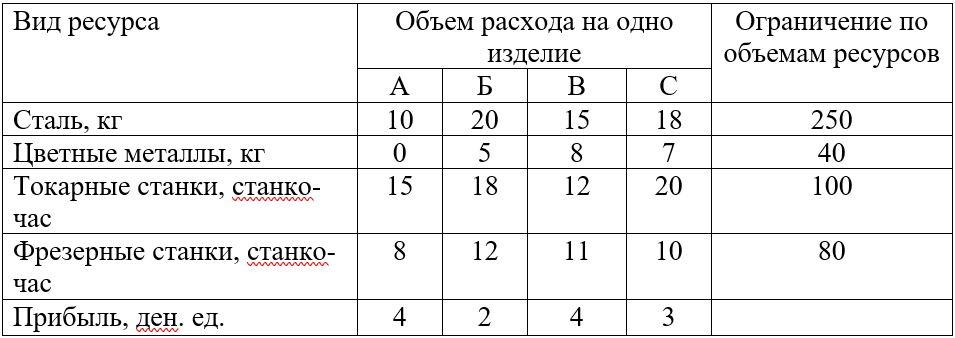


$$\begin{cases}
4*x_1+2*x_2+4*x_3+3*x_4 \rightarrow max
\\
5*x_2+8*x_3+7*x_4 \leq 40
\\
15*x_1+18*x_2+12*x_3+20*x_4 \leq 100
\\
8*x_1+12*x_2+11*x_3+10*x_4 \leq 80
\end{cases}$$


f = [4 2 4 3];
A = [0 5 8 7;
    15 18 12 20;
    8 12 11 10];
b = [40; 100; 80];
Aeq = [0 0 0 0];
beq = 0;
intcon = [1 2 3 4];
lb = [0; 0; 0; 0];
[x, fval] = intlinprog(-f, intcon, A, b, Aeq, beq, lb)

LP:                Optimal objective value is -30.666667.                                           

Cut Generation:    Applied 1 Gomory cut.                                                            
                   Lower bound is -28.000000.                                                       
                   Relative gap is 0.00%.                                                          


Optimal solution found.

Intlinprog stopped at the root node because the objective value is within a gap tolerance of the optimal
value, options.AbsoluteGapTolerance = 0 (the default value). The intcon variables are
integer within tolerance, options.IntegerTolerance = 1e-05 (the default value).



x =     2.0000
         0
    5.0000
         0


fval = -28

**ЗАДАЧА ****6.**  Фирма "Компьютер-сервис" поставляет компьютеры «под ключ» четырех базовых комплектаций:  «домашний», «игровой»,  «офисный»  и  «экстрим». Известны средние затраты времени на сборку, проверку и подключение компьютеров. Каждый компьютер приносит определенный уровень прибыли, но спрос ограничен. Кроме того, в плановом периоде ограничен ресурс человеко-часов, отведенных на выполнение каждой производственной операции. Определить, сколько компьютеров каждого типа необходимо произвести в плановом периоде, имея целью максимизировать прибыль.

 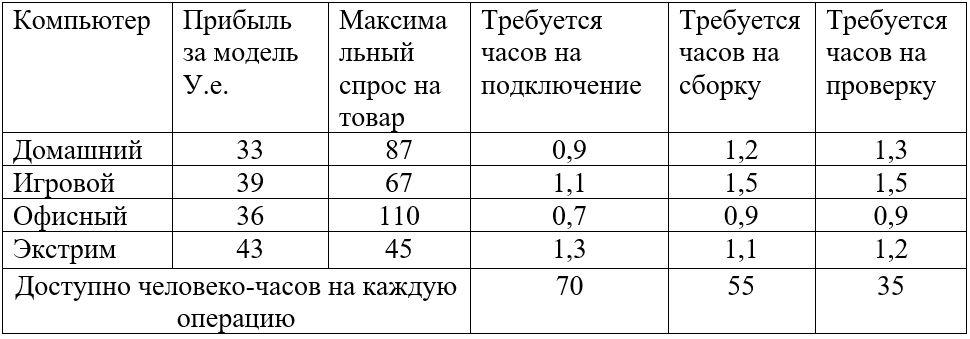


$$\begin{cases}
33*x_1+39*x_2+36*x_3+43*x_4 \rightarrow max
\\
0.9*x_1+1.1*x_2+0.7*x_3+1.3*x_4 \leq 70
\\
1.2*x_1+1.5*x_2+0.9*x_3+1.1*x_4 \leq 55
\\
1.3*x_1+1.5*x_2+0.9*x_3+1.2*x_4 \leq 35
\\
0 \leq x_1 \leq 87
\\
0 \leq x_2 \leq 67
\\
0 \leq x_3 \leq 110
\\
0 \leq x_4 \leq 45
\end{cases}$$


f = [33 39 36 43];
A = [0.9 1.1 0.7 1.3;
    1.2 1.5 0.9 1.1;
    1.3 1.5 0.9 1.2];
b = [70; 55; 35];
Aeq = [0 0 0 0];
beq = 0;
lb = [0; 0; 0; 0];
ub = [87; 67; 110; 45];
intcon = [1 2 3 4];
[x, fval] = intlinprog(-f, intcon, A, b, Aeq, beq, lb)

LP:                Optimal objective value is -1396.666667.                                         

Cut Generation:    Applied 2 Gomory cuts.                                                           
                   Lower bound is -1382.000000.                                                     
                   Relative gap is 0.00%.                                                          


Optimal solution found.

Intlinprog stopped at the root node because the objective value is within a gap tolerance of the optimal
value, options.AbsoluteGapTolerance = 0 (the default value). The intcon variables are
integer within tolerance, options.IntegerTolerance = 1e-05 (the default value).



x =          0
         0
   36.0000
    2.0000


fval = -1382

**ЗАДАЧА 7**.  На участке производства зубчатых колес имеются два станка — зубофрезерный и зубодолбежный. Требуется изготовить три вида зубчатых колес в следующих количествах: первого вида — 80 шт, второго и третьего — 110 и 140 штук соответственно. Каждое зубчатое колесо может быть изготовлено на любом из станков. Для выпуска одного колеса первого вида на зубофрезерном станке требуется затратить 20 мин, а на зубодолбежном — 34 мин. Для выпуска одного колеса второго вида на зубофрезерном станке требуется затратить 12 мин, а на зубодолбежном — 14 мин. Для выпуска одного колеса третьего вида требуется затратить 10 и 8 мин соответственно. Ресурс работы зубофрезерного станка без смены инструмента (фрезы) позволяет выпустить всего 180 колес, а ресурс работы зубодолбежного станка без смены инструмента (долбяка) позволяет выпустить всего 150 зубчатых колес. Определить оптимальную загрузку станков, обеспечивающую минимальное общее время их работы без смены инструмента.


$$\begin{cases}
20*x_1 + 12*x_2 + 10*x_3 + 34*x_{12} + 14*x_{22} + 8*x_{32} \rightarrow min
\\
x_1 + x_2 + x_3 \leq 180;
\\
x_{12} + x_{22} + x_{33} \leq 150
\\
x_1 + x_{21} = 80
\\
x_2 + x_{21} = 110
\\
x_3 + x_{31} = 140
\\
0 \leq x_1
\\
0 \leq x_2
\\
0 \leq x_3
\\
0\leq x_{12}
\\
0 \leq x_{22}
\\
0 \leq x_{32}
\end{cases}$$


f = [20 12 10 34 14 8];
A = [1 1 1 0 0 0;
    0 0 0 1 1 1];
b = [180; 150];
Aeq = [1 0 0 1 0 0;
    0 1 0 0 1 0;
    0 0 1 0 0 1];
beq = [80; 110; 140];
lb = [0; 0; 0; 0; 0; 0];
intcon = [1 2 3 4 5 6];
[x, fval] = intlinprog(f, intcon, A, b, Aeq, beq, lb)

LP:                Optimal objective value is 4060.000000.                                          


Optimal solution found.

Intlinprog stopped at the root node because the objective value is within a gap tolerance of the optimal
value, options.AbsoluteGapTolerance = 0 (the default value). The intcon variables are
integer within tolerance, options.IntegerTolerance = 1e-05 (the default value).



x =     80
   100
     0
     0
    10
   140


fval = 4060